# Expand Example 3.18:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

Signum function

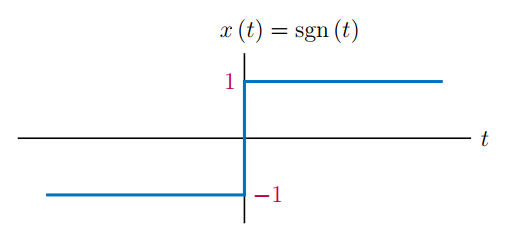

        $x(t)=\textrm{sgn}(t)=\left\{\begin{array}{c l}-1,&t<0\\1,&t>0\end{array}\right.$                    (3.150)

        $X(\omega)=\frac{2}{j\omega}$        (See Example 3.18 for details)

Define an intermediate signal as

        $p(t) = \left\{\,
\begin{array}{r l}
    -e^{at}\;, & t < 0  \\
     e^{-at}\;, & t > 0
\end{array}
\right.$                            (3.151)

so that

        
$$x(t)=\lim_{a\to 0} p(t)$$


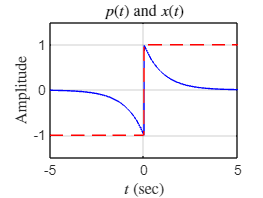

a = 1;
%
t = [-5:0.01:5];  % Vector of time instants
p = -exp(a*t).*(t<=0)+exp(-a*t).*(t>0);
x = 1*(t>=0)-1*(t<0);
omg = [-8:0.01:8];  % Vector of frequencies
% Compute the transform
Xomg = -j*2*omg./(a*a+omg.*omg);
% Graph the signals x(t) and p(t)
plot(t,p,'b-',t,x,'r--'); grid;
axis([-5,5,-1.5,1.5]);
set(0,'defaultTextInterpreter','latex');
xlabel('$t$ (sec)');
ylabel('Amplitude');
title('$p(t)$ and $x(t)$');

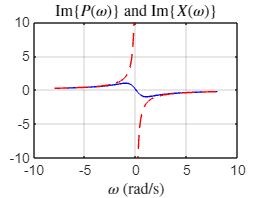

% Graph the imaginary part of the transform
plot(omg, imag(Xomg),'b-',omg,-2./omg,'r--'); grid;
axis([-10,10,-10,10]);
xlabel('$\omega$ (rad/s)');
title('Im$\{P(\omega)\}$ and Im$\{X(\omega)\}$');

set(0,'defaultTextInterpreter','tex');